# Antenna Array Design and Analysis

L = design(linearArray, 77e9, patchMicrostrip)

L =   linearArray with properties:

           Element: [1×1 patchMicrostrip]
       NumElements: 2
    ElementSpacing: 0.0019
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


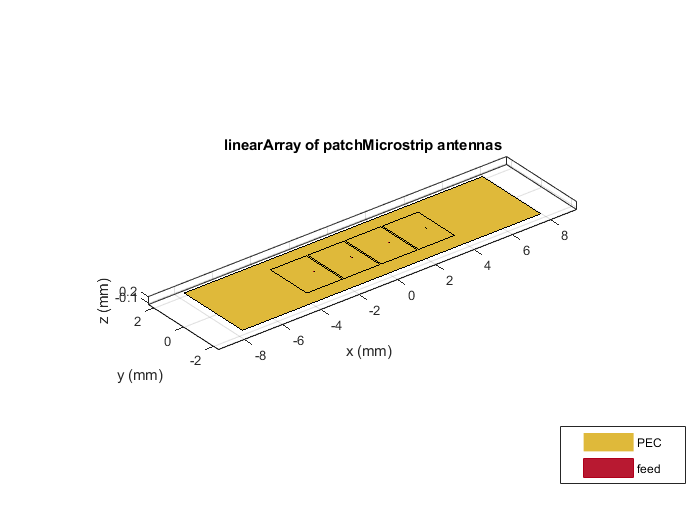

L.NumElements = 4;
show(L)

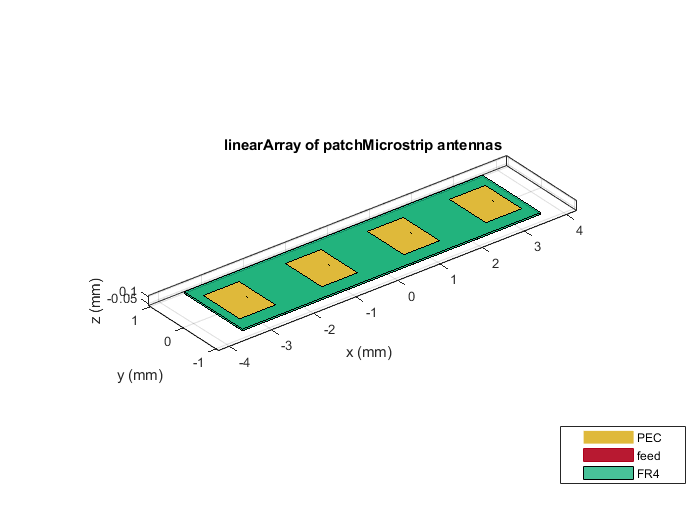

load("patchMicrostripDielectric.mat")
L.Element = patchD;
show(L)

L.ElementSpacing = L.ElementSpacing/2.2

L =   linearArray with properties:

           Element: [1×1 patchMicrostrip]
       NumElements: 4
    ElementSpacing: 8.8487e-04
    AmplitudeTaper: 1
        PhaseShift: 0
              Tilt: 0
          TiltAxis: [1 0 0]


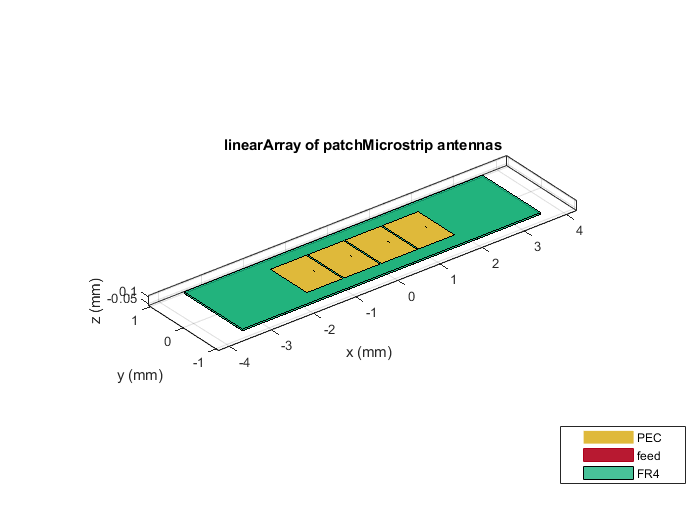

show(L)

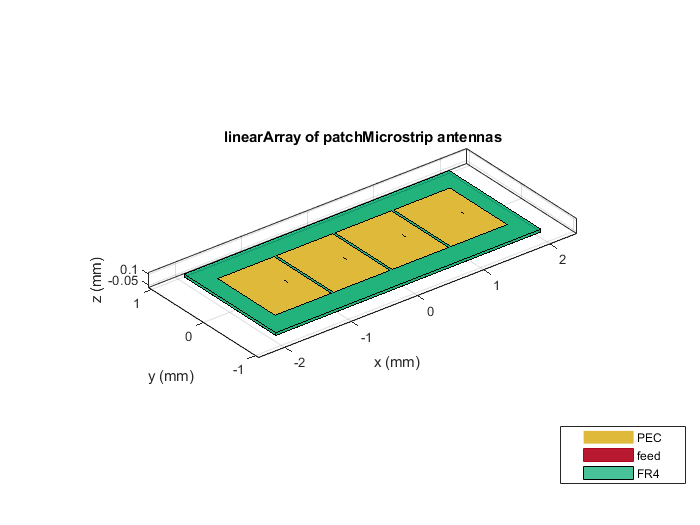

L.Element.GroundPlaneLength = 1e-3;
show(L);

Load pre-computed results to speed up analysis.

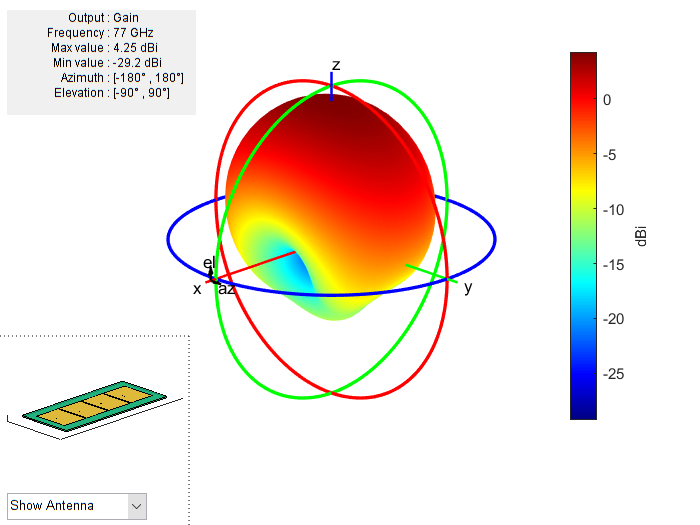

pattern(L, 77e9)

patternElevation(L, 77e9, 0);

Load pre-computed results to speed up analysis.

impedance(L, (69:84)*1e9)

S = sparameters(L,( 69:84)*1e9)
rfplot(S)